# Power-Split HEV with Speed Tracking - Simple Drive Pattern

## Open the Model

mdl = "PowerSplitHEV_SpeedTracking";
if not(bdIsLoaded(mdl)), load_system(mdl); end

## Load Inputs to Workspace

input_pattern = "simple_drive_pattern";

Load vehicle speed reference

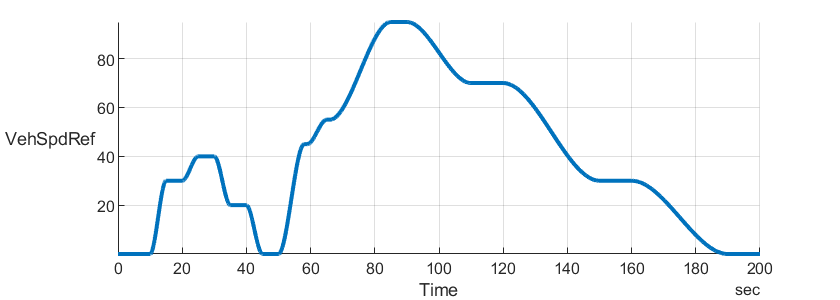

fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, initial_DrvPtn, opt1] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig, "PlotSpeedOnly",true, ...
    "InputPattern", input_pattern );
fig.Position(4) = 200;  % height

drivingPattern.useFromWorkspace_tf = opt1.useFromWorkspace;

Load road grade

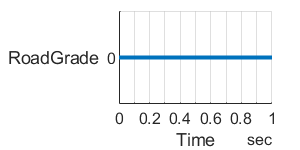

fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( "PlotParent",fig, "InputPattern", "flat" );
fig.Position(3:4) = [200 100];  % width height

Set simulation time

t_end = max(opt1.t_end, opt2.t_end);

dt = 0;  % 0 for variable-step solver

## Run Simulation

Load default parameters

PowerSplitHEV_params

Override initial conditions and block parameter values

% Initial SOC in the controller
%initial.driverHVBattSOC_pct = initial_DrvPtn.HVBattery_SOC_pct;
initial.driverHVBattSOC_pct = 75;

% Initial charge in the plant, which must be consistent with initial SOC
initial.highVoltageBatterySOC_pct = initial.driverHVBattSOC_pct;
initial.hvBatteryCharge_Ah = batteryHighVoltage.nominalCharge_Ah * initial.highVoltageBatterySOC_pct/100;

initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

Set simulation input

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

in = in.setModelParameter('SolverName','ode23t');

Run simulation

out = sim(in);

Simulated time (sec)

t_end

t_end = 200

Elapsed wall-clock time (sec)

t_elapsed = out.SimulationMetadata.TimingInfo.TotalElapsedWallTime

t_elapsed = 6.1535

Speed up

t_end / t_elapsed

ans = 32.5016

## Visualize Simulation Result

Vehicle

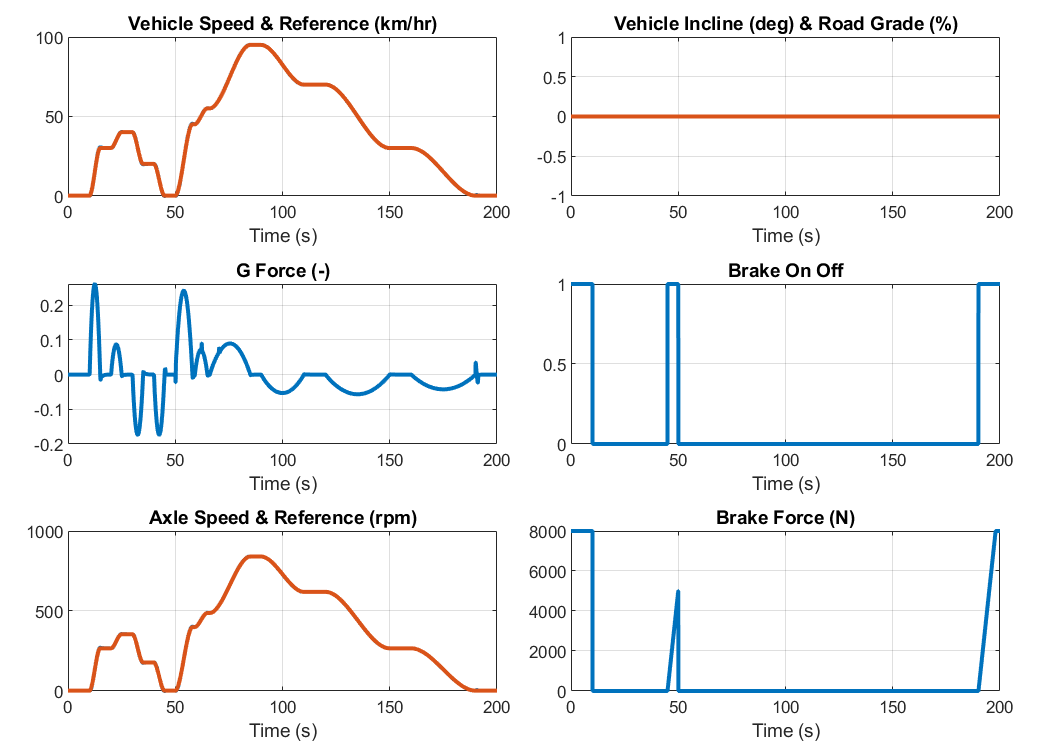

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_vehicle( "Dataset",out.logsout, "PlotParent",fig );

High Voltage Battery

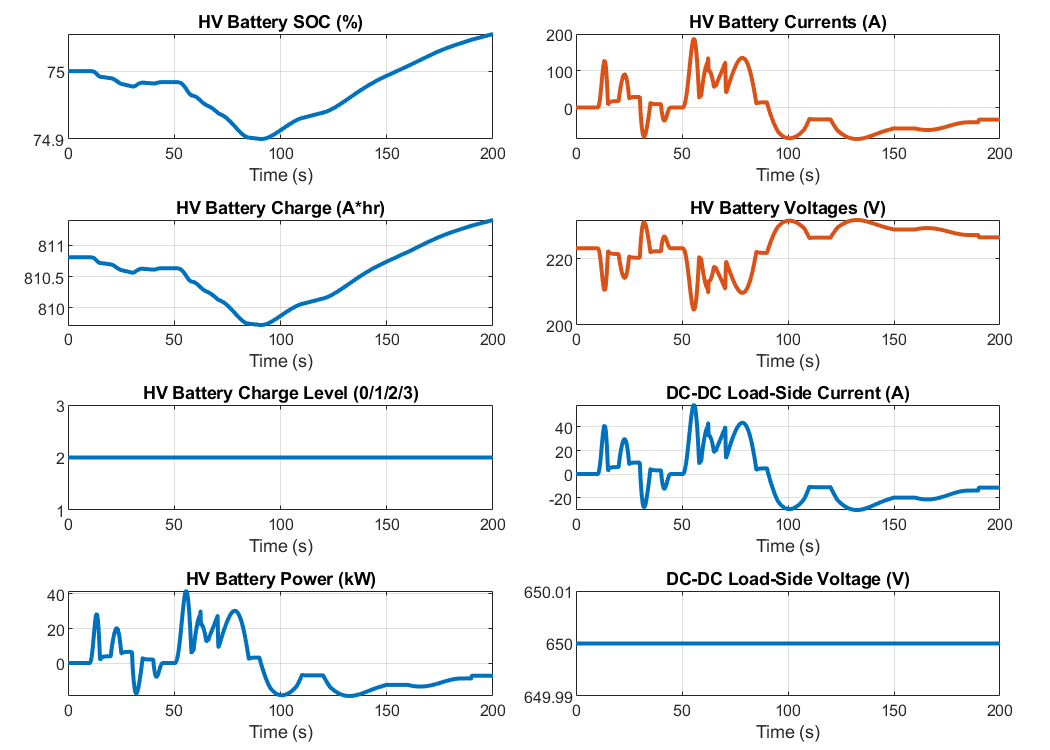

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_hvbattery( "Dataset",out.logsout, "PlotParent",fig );

Power-Split Drive Unit

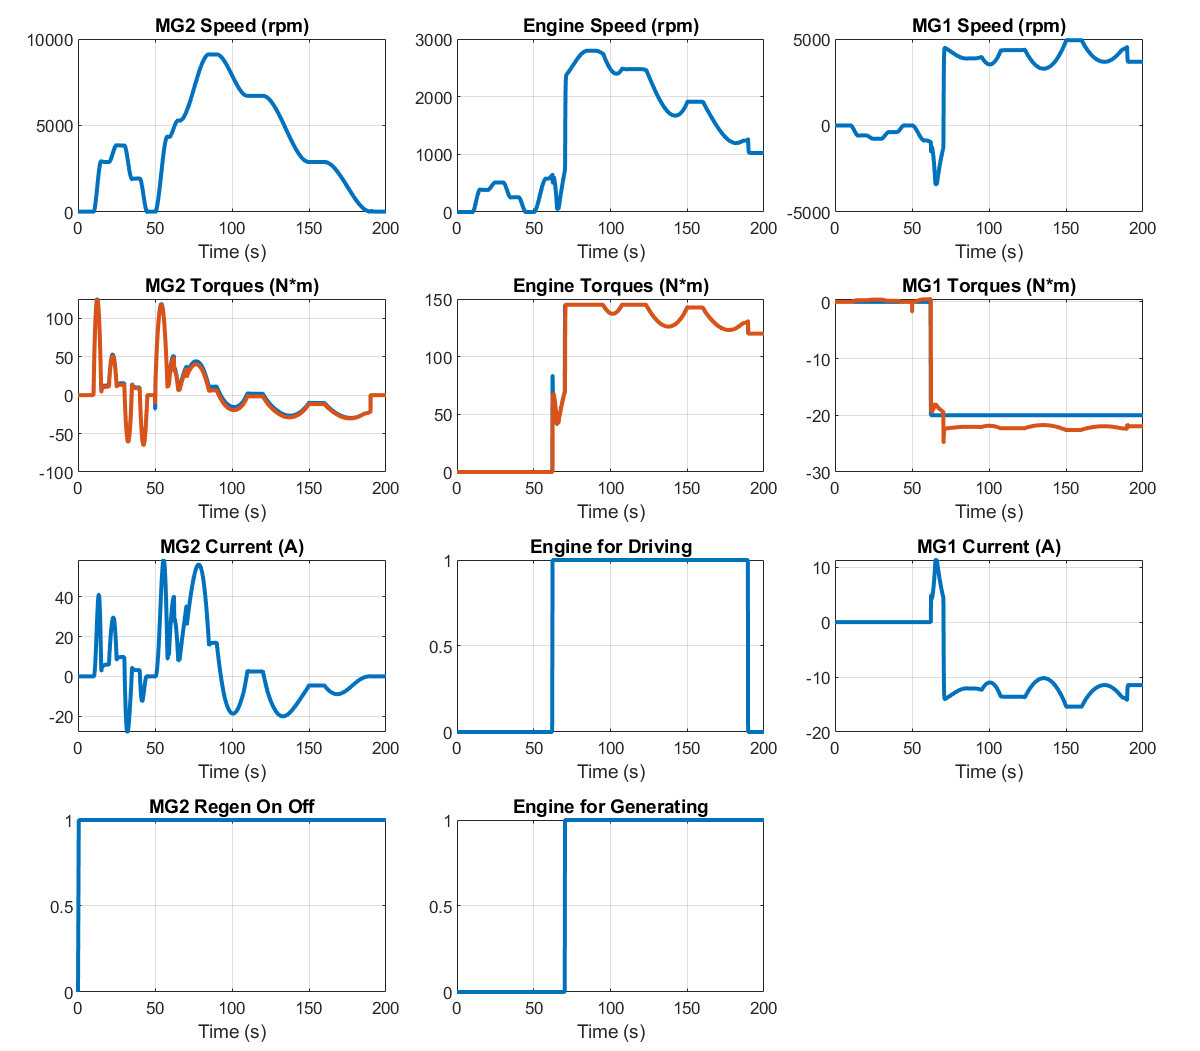

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_powersplit( "Dataset",out.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*